close all; clear;
%一些参数
c = 3e8; %光速
fc = 2123e6; %发射信号载频 中心频率
bw = 10e6; %发射信号的带宽
Ts = 4e-8; %扫频时间，即周期
fs = 25e6; %数据的采样率
T = 0.5; %时间间隔
N = T/Ts; %采样点
delay = 2e-7;
fD = -40:2:40; %Time Doppler Spectrum的横轴范围
range = 0:0.5:9.5; %Time Doppler Spectrum的纵轴范围
TD = zeros(20,41); %记录每个格子的值
m_max = 0; %记录cor的最大值

%处理数据
addpath('F:\Soymilk\Curricula\Sophomore\Signals and Systems\lab\07\data_preprocessed');
for idx_time =1:1:20
    load(sprintf('data_preprocessed/data_%d_preprocessed.mat',idx_time)); %加载数据
    ref_shift_LP_fft = conj(fft(ref_shift_LP));
    for col = -40:2:40
     m = sur_shift_LP.*exp(-1i*2*pi*col*(0:N-1)/fs);
     m = fft(m);
     m = ifft(duration.*m.*ref_shift_LP_fft);
     m = abs(m);
     for tau = 0:1:6
         if m(tau+1) > m_max %找最大值
             m_max = m(tau+1);
         end
     end
     TD(idx_time,col/2+21) = m_max; %将最大值记入TD矩阵中
     m_max = 0; %最大值归零
    end
end

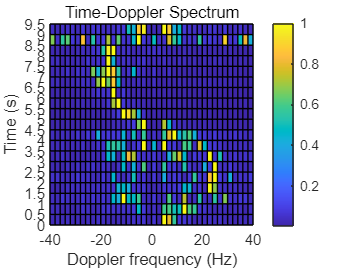

% plot Time Doppler Spectrum
[X,Y]=meshgrid(fD,range);
figure(1);
TD_l = TD ./ max(TD,[],2);
max_TD = max(TD_l,2);
for row = 1:20
    for col = 1:41
        if TD_l(row,col) < (max_TD(row)*0.2)
            TD_l(row,col) = TD_l(row,col) * 0.2;
        end
    end
end
surf(X,Y,TD_l);
view(0,90);colorbar;
xlim([fD(1),fD(end)]);ylim([range(1),range(end)]);
xlabel('Doppler frequency (Hz)');ylabel('Time (s)');
xticks(fD(1):20:fD(end))
yticks(range(1):0.5:range(end)+duration);
title('Time-Doppler Spectrum');